% load new models
clear
param.tissueSpecificSolver='thermoKernel';
switch param.tissueSpecificSolver
    case 'fastCore'
        baseFolderNew='~/drive/bioenergeticsPD/results/model/fastcore';
        load([baseFolderNew filesep 'synaptic_model/synaptic_model.mat'])
        load([baseFolderNew filesep 'synapticPD_model/synapticPD_model.mat'])
        load([baseFolderNew filesep 'synaptic_model/nonsynaptic_model.mat'])
        load([baseFolderNew filesep 'synapticPD_model/nonsynapticPD_model.mat'])
    case 'thermoKernel'
        baseFolderNew='~/drive/bioenergeticsPD/results/model/thermokernel';
        load([baseFolderNew filesep 'test_SYN_new_model/SYN.mat'])
        load([baseFolderNew filesep 'test_SYNPD_new_model/SYNPD.mat'])
        load([baseFolderNew filesep 'test_ASYN_new_model/ASYN.mat'])
        load([baseFolderNew filesep 'test_ASYNPD_new_model/ASYNPD.mat'])
end

% load all models
multiModels.SYN=SYN;
multiModels.SYNPD=SYNPD;
multiModels.ASYN=ASYN;
multiModels.ASYNPD=ASYNPD;

% model characteristics
[CharacteristicTable1] = ModelCharacteristic(multiModels,1);

CharacteristicTable = 10×4 table
                                            SYN     SYNPD    ASYN    ASYNPD
                                            ____    _____    ____    ______

    Total num of genes                      1317    1317     1339     1310 
    Total num of genes in the mito           340     346      348      335 
    Total num of reactions                  2405    2405     2508     2306 
    Total num of reactions in the mito       519     532      555      508 
    Total num of metabolites                 761     753      767      728 
    Total num of metabolites in the mito     296     303      306      281 
    Total num of transport reactions        1040    1028     1074      981 
    Total num of ex

resultFolder = '~/drive/bioenergeticsPD/results/analysis/Modelcomparison';
% writetable(CharacteristicTable1,[resultFolder filesep 'ModelCharacteristics/modelCharacteristics.xlsx'],'WriteRowNames', true);

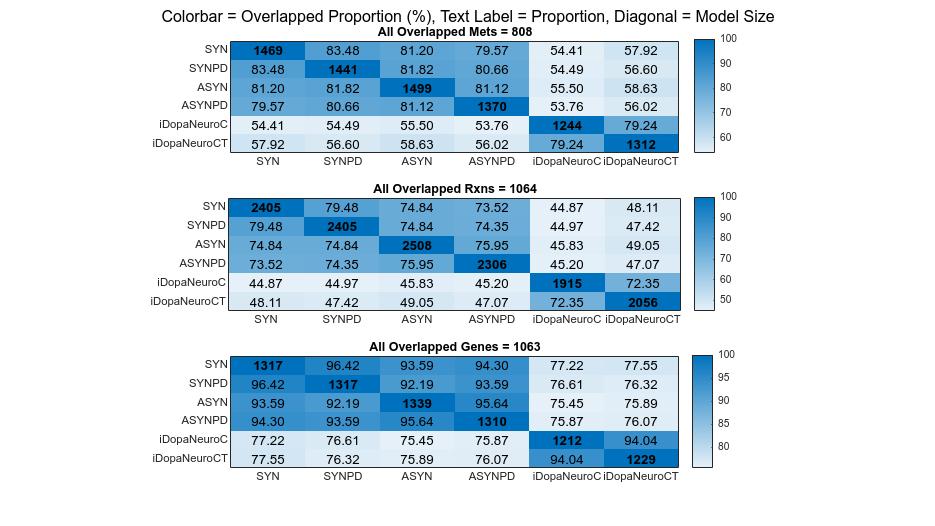

load('~/drive/metaPD/data/DN_models/version2/iDopaNeuro/iDopaNeuroC.mat')
load('~/drive/metaPD/data/DN_models/version2/iDopaNeuro/iDopaNeuroCT.mat')
multiModels.iDopaNeuroC=iDopaNeuroC;
multiModels.iDopaNeuroCT=iDopaNeuroCT;
%compare the overlapped reactions, metabolites, and genes between models
[overlapResults,statistic]=compareXomicsModels(multiModels,0);
plotOverlapResults(overlapResults,statistic)

% Save as an EPS file
% print([resultFolder filesep 'OverlapResults.eps'], '-depsc');

if 0
    % core(replicated) metabolites
    inputFolder = '~/drive/metaPD/data/metabolomics/inputData';
    bibliomicData = 'PD_test4_withcorerxns.xlsx';
    specificData = preprocessingOmicsModel([inputFolder filesep bibliomicData], 1, 1);

Reading inputData from : ~/drive/metaPD/data/metabolomics/inputData/PD_test4_withcorerxns.xlsx
Reading sheet: activeReactions
Reading sheet: presentMetabolites


    PDmets=specificData.presentMetabolites.mets;
    % ignore caffeine mets (not in the model)
    caffeineMets={'cfn1','theophylline1','pxthn1','17dmurt1','137tmurica1','1mxnt','5acam6am3mura','5acam6fam3mura',...
        'theobromine1','7mxth','1murt','37dmur','7murt'};
    PDmets(ismember(PDmets,caffeineMets))=[];
    % check 127 PD mets with each model
    models=fieldnames(multiModels);
    comparePDmets=cell(1,length(models));
    for i = 1:length(models)
        model= multiModels.(models{i});
        % count the included PD mets
        metsnew=unique(regexprep(model.mets,'(\[\w\])',''));
        comparePDmets{1,i} = sum(ismember(metsnew,PDmets));
        % count the involved PD rxns
        allPDmets= model.mets(ismember(metsnew,PDmets));
        rxns=findRxnsFromMets(model,allPDmets);
        comparePDmets{2,i} = length(rxns);
        % count the involved PD genes
        genes =findGenesFromRxns(model,rxns);
        genes(find(cellfun(@isempty,genes)))=[];
        uniquegenes = [];
        for m = 1:length(genes)
            uniquegenes = [uniquegenes; genes{m}(:)];
        end
        comparePDmets{3,i} = length(unique(uniquegenes));
        % count the involved PD subsystems
        subsystems=model.subSystems(ismember(model.rxns,rxns));
        comparePDmets{4,i} = length(unique(subsystems));
    end
    comparePDmets= cell2table(comparePDmets);
    comparePDmets.Properties.VariableNames=models;
    comparePDmets.Properties.RowNames={'Total num of PD mets','Total num of PD rxns','Total num of PD genes','Total num of PD subsystems'}

comparePDmets = 4×6 table
                                  SYN2    SYNPD    ASYN    ASYNPD    iDopaNeuroC    iDopaNeuroCT
                                  ____    _____    ____    ______    ___________    ____________

    Total num of PD mets           83       80      83       83           72             75     
    Total num of PD rxns          510      418     546      487          310            379     
    Total num of PD genes         460      384     492      446          414            430     
    Total num of PD subsystems     59       49      61       56           51             55     


    % overlapped subsystems?
end